# UR5e Control for RoboCup ARM Challenge

## Códigos generados de la información de MATLAB

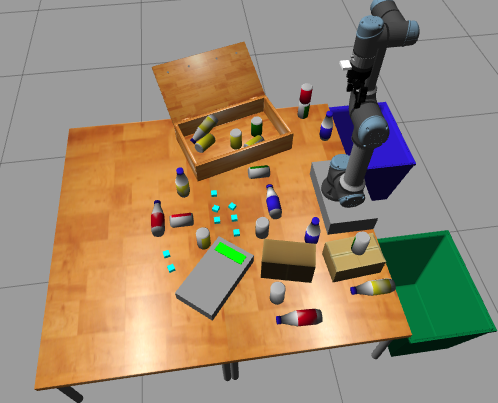

Funciones que definiremos:

Conectar Matlab y Gazebo --> IniciarRobot

Leer valores articulares y gripper --> LeerValoresArticulares

Abrimos y cerramos el gripper --> ActivacionGripper

Resolvemos el problema de cinemática inversa --> UnaSolucionesUR5e

## Conectando Matlab y Gazebo

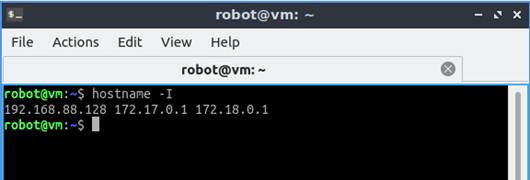

rosIP = '172.17.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Initializing global node /matlab_global_node_63575 with NodeURI http://PCIrandi:34777/ and MasterURI http://172.17.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates                                  
/gazebo/performance_metrics                                
/gazebo/set_link_state            

%jointSub : Receive current robot configuration
%trajGoal : Paquete que contiene información de movimiento articular deseado
%trajAct  : Cliente que recibe el trajGoal
%gripGoal : Paquete que contiene información de movimiento del gripper
%gripAct  : Cliente que recibe el gripGoal
%rgbImgSub: Recibe la información de la cámara RGB
%rgbDptSub: Recibe la información de la cámara de profundidad

## Leyendo los valores articulares

ValoresArticulares = LeerValoresArticulares(jointSub)

ValoresArticulares = struct with fields:
         q1: 5.4419
         q2: 0.8628
         q3: 4.1700
         q4: 4.3920
         q5: 3.1416
         q6: 7.0127
    Gripper: 1.1263e-05


%ValoresArticulares : Recibe las 6 coordenadas articulares y el valor del

## Abriendo y cerrando el gripper

ValorGripper = 0.8;    %0 abierto/desactivado 0.8 cerrado/activado
ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
%Función que abre y cierra el gripper, para que esta función se itere hasta
%que culmine la acciòn deberá entrar al código y descomentar la sección
%correspondiente

## Moviendo el robot a nivel articular

q =zeros(6,1);
q(1) =-0.9;
q(2) =-0.5;
q(3) =1.9;
q(4) =-1.3;
q(5) =0;
q(6) =1.1;

MoverRobot(q,trajAct,trajGoal,jointSub);
%Función que mueve las articulaciones del robot, para que esta función se itere hasta
%que culmine la acción deberá entrar al código y descomentar la sección
%correspondiente

## Cinemática inversa usando la funcion de inverseKinematics de Matlab

UR5e = loadrobot('universalUR5e')

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


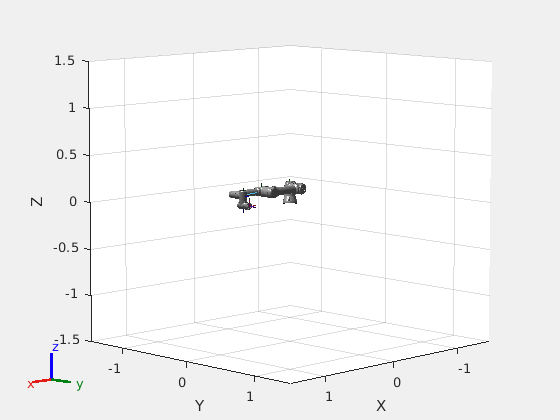

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


configSoln = homeConfiguration(UR5e);
show(UR5e,configSoln)


% Ajuste de la transformación de cuerpos de la versión previa del robot
% tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
% UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

figure
show(UR5e,configSoln)

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



%
ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver
ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation



### Posición de tool0.

Busquemos una posición del gripper que sea correcta. Probemos (x, y, z)=(0, 0.31, 0.42)

gripperX = 0.01;
gripperY = 0.31;
gripperZ = 0.42;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotation = [-pi/2 -pi 0]; %  [Z Y X]radians


tform = eul2tform(gripperRotation); %
tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
tic 
[configSoln, solnInfo] =ik('tool0',tform,ikWeights,configSoln)

Unrecognized function or variable 'ikWeights'.

toc
show(UR5e,configSoln)

q = zeros(6,1);
for n = 1:6
    q(n) = configSoln(n).JointPosition;
end
q = mod(q-pi,2*pi)-pi

MoverRobot(q,trajAct,trajGoal,jointSub);

## Cinemática inversa usando la solución exacta.

q = zeros(6,1);

gripperX = 0.01;
gripperY = 0.52;
gripperZ = 0.42;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotation = [-pi/2 -pi 0]; %  [Z Y X]radians


tform = eul2tform(gripperRotation); %
tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform
tic
q = UnaSolucionesUR5e(tform,q);
%Función que resuelve el problema de cinemàtica inversa, recibe el valor de
%la matriz homogénea a la que deseamos llegar, y la posición articular de
%la que partimos
toc

Elapsed time is 0.036620 seconds.


q = q + [pi pi/2 0 0 pi/2 0]'; %Correción de parámetros.

for k = 1:6
        configSoln(k).JointPosition = q(k);
end

show(UR5e,configSoln)

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



MoverRobot(q,trajAct,trajGoal,jointSub);

ValoresArticulares = struct with fields:
         q1: 5.4375
         q2: 0.8619
         q3: 4.1735
         q4: 4.3926
         q5: 3.1383
         q6: 7.0100
    Gripper: 1.1264e-05


ans = 12.1360

ValoresArticulares = struct with fields:
         q1: 5.4118
         q2: 0.8569
         q3: 4.1945
         q4: 4.3961
         q5: 3.1188
         q6: 6.9940
    Gripper: 1.1271e-05


ans = 12.1168

ValoresArticulares = struct with fields:
         q1: 5.4054
         q2: 0.8556
         q3: 4.1998
         q4: 4.3970
         q5: 3.1139
         q6: 6.9900
    Gripper: 1.1313e-05


ans = 12.1121

ValoresArticulares = struct with fields:
         q1: 5.4011
         q2: 0.8548
         q3: 4.2033
         q4: 4.3976
         q5: 3.1107
         q6: 6.9873
    Gripper: 1.1315e-05


ans = 12.1089

ValoresArticulares = struct with fields:
         q1: 5.3973
         q2: 0.8541
         q3: 4.2063
         q4: 4.3981
         q5: 3.1079
         q6: 6.9850
    Gripper: 1.1276e-05


ans = 12.1062

ValoresArticulares = struct with fields:
         q1: 5.3942
         q2: 0.8535
         q3: 4.2089
         q4: 4.3986
         q5: 3.1055
         q6: 6.9830
    Gripper: 1.1319e-05


ans = 12.1038

ValoresArticulares = struct with fields:
         q1: 5.3883
         q2: 0.8523
         q3: 4.2137
         q4: 4.3994
         q5: 3.1010
         q6: 6.9794
    Gripper: 1.1336e-05


ans = 12.0995

ValoresArticulares = struct with fields:
         q1: 5.3874
         q2: 0.8521
         q3: 4.2144
         q4: 4.3995
         q5: 3.1004
         q6: 6.9788
    Gripper: 1.1279e-05


ans = 12.0989

ValoresArticulares = struct with fields:
         q1: 5.3857
         q2: 0.8518
         q3: 4.2158
         q4: 4.3997
         q5: 3.0990
         q6: 6.9777
    Gripper: 1.1337e-05


ans = 12.0976

ValoresArticulares = struct with fields:
         q1: 5.3848
         q2: 0.8516
         q3: 4.2166
         q4: 4.3998
         q5: 3.0983
         q6: 6.9772
    Gripper: 1.1280e-05


ans = 12.0969

ValoresArticulares = struct with fields:
         q1: 5.3839
         q2: 0.8514
         q3: 4.2173
         q4: 4.4000
         q5: 3.0977
         q6: 6.9766
    Gripper: 1.1323e-05


ans = 12.0962

ValoresArticulares = struct with fields:
         q1: 5.3801
         q2: 0.8507
         q3: 4.2204
         q4: 4.4005
         q5: 3.0948
         q6: 6.9743
    Gripper: 1.1338e-05


ans = 12.0935

ValoresArticulares = struct with fields:
         q1: 5.3438
         q2: 0.8436
         q3: 4.2500
         q4: 4.4054
         q5: 3.0674
         q6: 6.9518
    Gripper: 1.1344e-05


ans = 12.0670

ValoresArticulares = struct with fields:
         q1: 5.3374
         q2: 0.8424
         q3: 4.2552
         q4: 4.4063
         q5: 3.0625
         q6: 6.9478
    Gripper: 1.1347e-05


ans = 12.0623

ValoresArticulares = struct with fields:
         q1: 5.3308
         q2: 0.8411
         q3: 4.2606
         q4: 4.4072
         q5: 3.0575
         q6: 6.9436
    Gripper: 1.1300e-05


ans = 12.0575

ValoresArticulares = struct with fields:
         q1: 5.3281
         q2: 0.8406
         q3: 4.2628
         q4: 4.4076
         q5: 3.0554
         q6: 6.9419
    Gripper: 1.1348e-05


ans = 12.0555

ValoresArticulares = struct with fields:
         q1: 5.3211
         q2: 0.8392
         q3: 4.2685
         q4: 4.4085
         q5: 3.0501
         q6: 6.9376
    Gripper: 1.1356e-05


ans = 12.0504

ValoresArticulares = struct with fields:
         q1: 5.3196
         q2: 0.8389
         q3: 4.2697
         q4: 4.4087
         q5: 3.0490
         q6: 6.9367
    Gripper: 1.1350e-05


ans = 12.0494

ValoresArticulares = struct with fields:
         q1: 5.3182
         q2: 0.8386
         q3: 4.2709
         q4: 4.4089
         q5: 3.0479
         q6: 6.9358
    Gripper: 1.1305e-05


ans = 12.0483

ValoresArticulares = struct with fields:
         q1: 5.3138
         q2: 0.8378
         q3: 4.2744
         q4: 4.4095
         q5: 3.0446
         q6: 6.9331
    Gripper: 1.1307e-05


ans = 12.0452

ValoresArticulares = struct with fields:
         q1: 5.3123
         q2: 0.8375
         q3: 4.2757
         q4: 4.4097
         q5: 3.0435
         q6: 6.9322
    Gripper: 1.1360e-05


ans = 12.0441

ValoresArticulares = struct with fields:
         q1: 5.3033
         q2: 0.8357
         q3: 4.2831
         q4: 4.4110
         q5: 3.0366
         q6: 6.9265
    Gripper: 1.1365e-05


ans = 12.0376

ValoresArticulares = struct with fields:
         q1: 5.2686
         q2: 0.8290
         q3: 4.3114
         q4: 4.4157
         q5: 3.0104
         q6: 6.9050
    Gripper: 1.1391e-05


ans = 12.0127

ValoresArticulares = struct with fields:
         q1: 5.2614
         q2: 0.8276
         q3: 4.3172
         q4: 4.4167
         q5: 3.0050
         q6: 6.9005
    Gripper: 1.1357e-05


ans = 12.0076

ValoresArticulares = struct with fields:
         q1: 5.2448
         q2: 0.8243
         q3: 4.3308
         q4: 4.4189
         q5: 2.9924
         q6: 6.8902
    Gripper: 1.1366e-05


ans = 11.9957

ValoresArticulares = struct with fields:
         q1: 5.2352
         q2: 0.8224
         q3: 4.3386
         q4: 4.4203
         q5: 2.9851
         q6: 6.8842
    Gripper: 1.1387e-05


ans = 11.9889

ValoresArticulares = struct with fields:
         q1: 5.2293
         q2: 0.8213
         q3: 4.3434
         q4: 4.4211
         q5: 2.9806
         q6: 6.8806
    Gripper: 1.1372e-05


ans = 11.9847

ValoresArticulares = struct with fields:
         q1: 5.2253
         q2: 0.8205
         q3: 4.3467
         q4: 4.4216
         q5: 2.9776
         q6: 6.8781
    Gripper: 1.1372e-05


ans = 11.9819

ValoresArticulares = struct with fields:
         q1: 5.2233
         q2: 0.8201
         q3: 4.3483
         q4: 4.4219
         q5: 2.9761
         q6: 6.8768
    Gripper: 1.1393e-05


ans = 11.9805

ValoresArticulares = struct with fields:
         q1: 5.2192
         q2: 0.8193
         q3: 4.3516
         q4: 4.4224
         q5: 2.9730
         q6: 6.8743
    Gripper: 1.1394e-05


ans = 11.9776

ValoresArticulares = struct with fields:
         q1: 5.2131
         q2: 0.8181
         q3: 4.3566
         q4: 4.4233
         q5: 2.9684
         q6: 6.8705
    Gripper: 1.1383e-05


ans = 11.9733

ValoresArticulares = struct with fields:
         q1: 5.2047
         q2: 0.8165
         q3: 4.3634
         q4: 4.4244
         q5: 2.9620
         q6: 6.8653
    Gripper: 1.1385e-05


ans = 11.9674

ValoresArticulares = struct with fields:
         q1: 5.2005
         q2: 0.8157
         q3: 4.3669
         q4: 4.4250
         q5: 2.9588
         q6: 6.8627
    Gripper: 1.1434e-05


ans = 11.9644

ValoresArticulares = struct with fields:
         q1: 5.1984
         q2: 0.8153
         q3: 4.3686
         q4: 4.4253
         q5: 2.9572
         q6: 6.8613
    Gripper: 1.1388e-05


ans = 11.9629

ValoresArticulares = struct with fields:
         q1: 5.1719
         q2: 0.8101
         q3: 4.3902
         q4: 4.4289
         q5: 2.9372
         q6: 6.8449
    Gripper: 1.1388e-05


ans = 11.9444

ValoresArticulares = struct with fields:
         q1: 5.1558
         q2: 0.8069
         q3: 4.4034
         q4: 4.4311
         q5: 2.9250
         q6: 6.8349
    Gripper: 1.1398e-05


ans = 11.9332

ValoresArticulares = struct with fields:
         q1: 5.1534
         q2: 0.8065
         q3: 4.4053
         q4: 4.4314
         q5: 2.9232
         q6: 6.8334
    Gripper: 1.1403e-05


ans = 11.9316

ValoresArticulares = struct with fields:
         q1: 5.1318
         q2: 0.8023
         q3: 4.4229
         q4: 4.4344
         q5: 2.9068
         q6: 6.8200
    Gripper: 1.1415e-05


ans = 11.9166

ValoresArticulares = struct with fields:
         q1: 5.1144
         q2: 0.7989
         q3: 4.4371
         q4: 4.4367
         q5: 2.8937
         q6: 6.8092
    Gripper: 1.1427e-05


ans = 11.9047

ValoresArticulares = struct with fields:
         q1: 5.1119
         q2: 0.7984
         q3: 4.4392
         q4: 4.4371
         q5: 2.8917
         q6: 6.8076
    Gripper: 1.1428e-05


ans = 11.9029

ValoresArticulares = struct with fields:
         q1: 5.0939
         q2: 0.7949
         q3: 4.4539
         q4: 4.4395
         q5: 2.8781
         q6: 6.7964
    Gripper: 1.1440e-05


ans = 11.8906

ValoresArticulares = struct with fields:
         q1: 5.0913
         q2: 0.7944
         q3: 4.4560
         q4: 4.4399
         q5: 2.8761
         q6: 6.7948
    Gripper: 1.1442e-05


ans = 11.8888

ValoresArticulares = struct with fields:
         q1: 5.0860
         q2: 0.7933
         q3: 4.4603
         q4: 4.4406
         q5: 2.8722
         q6: 6.7915
    Gripper: 1.1445e-05


ans = 11.8852

ValoresArticulares = struct with fields:
         q1: 5.0618
         q2: 0.7886
         q3: 4.4800
         q4: 4.4439
         q5: 2.8538
         q6: 6.7765
    Gripper: 1.1462e-05


ans = 11.8688

ValoresArticulares = struct with fields:
         q1: 5.0452
         q2: 0.7854
         q3: 4.4935
         q4: 4.4462
         q5: 2.8413
         q6: 6.7662
    Gripper: 1.1474e-05


ans = 11.8576

ValoresArticulares = struct with fields:
         q1: 5.0311
         q2: 0.7826
         q3: 4.5051
         q4: 4.4481
         q5: 2.8306
         q6: 6.7574
    Gripper: 1.1484e-05


ans = 11.8481

ValoresArticulares = struct with fields:
         q1: 5.0196
         q2: 0.7804
         q3: 4.5144
         q4: 4.4497
         q5: 2.8219
         q6: 6.7503
    Gripper: 1.1492e-05


ans = 11.8404

ValoresArticulares = struct with fields:
         q1: 5.0109
         q2: 0.7787
         q3: 4.5215
         q4: 4.4509
         q5: 2.8153
         q6: 6.7448
    Gripper: 1.1499e-05


ans = 11.8346

ValoresArticulares = struct with fields:
         q1: 5.0080
         q2: 0.7781
         q3: 4.5239
         q4: 4.4513
         q5: 2.8131
         q6: 6.7430
    Gripper: 1.1501e-05


ans = 11.8327

ValoresArticulares = struct with fields:
         q1: 5.0021
         q2: 0.7770
         q3: 4.5287
         q4: 4.4521
         q5: 2.8086
         q6: 6.7394
    Gripper: 1.1506e-05


ans = 11.8288

ValoresArticulares = struct with fields:
         q1: 4.9962
         q2: 0.7758
         q3: 4.5336
         q4: 4.4529
         q5: 2.8041
         q6: 6.7357
    Gripper: 1.1510e-05


ans = 11.8248

ValoresArticulares = struct with fields:
         q1: 4.9932
         q2: 0.7752
         q3: 4.5360
         q4: 4.4533
         q5: 2.8019
         q6: 6.7338
    Gripper: 1.1512e-05


ans = 11.8228

ValoresArticulares = struct with fields:
         q1: 4.9902
         q2: 0.7746
         q3: 4.5384
         q4: 4.4537
         q5: 2.7996
         q6: 6.7320
    Gripper: 1.1514e-05


ans = 11.8209

ValoresArticulares = struct with fields:
         q1: 4.9872
         q2: 0.7741
         q3: 4.5409
         q4: 4.4541
         q5: 2.7973
         q6: 6.7301
    Gripper: 1.1516e-05


ans = 11.8189

ValoresArticulares = struct with fields:
         q1: 4.9842
         q2: 0.7735
         q3: 4.5433
         q4: 4.4545
         q5: 2.7951
         q6: 6.7282
    Gripper: 1.1519e-05


ans = 11.8169

ValoresArticulares = struct with fields:
         q1: 4.9378
         q2: 0.7644
         q3: 4.5812
         q4: 4.4608
         q5: 2.7599
         q6: 6.6994
    Gripper: 1.1554e-05


ans = 11.7864

ValoresArticulares = struct with fields:
         q1: 4.9218
         q2: 0.7613
         q3: 4.5942
         q4: 4.4630
         q5: 2.7478
         q6: 6.6895
    Gripper: 1.1567e-05


ans = 11.7760

ValoresArticulares = struct with fields:
         q1: 4.9121
         q2: 0.7594
         q3: 4.6021
         q4: 4.4643
         q5: 2.7405
         q6: 6.6835
    Gripper: 1.1625e-05


ans = 11.7697

ValoresArticulares = struct with fields:
         q1: 4.8825
         q2: 0.7536
         q3: 4.6263
         q4: 4.4684
         q5: 2.7181
         q6: 6.6650
    Gripper: 1.1608e-05


ans = 11.7505

ValoresArticulares = struct with fields:
         q1: 4.8657
         q2: 0.7504
         q3: 4.6400
         q4: 4.4707
         q5: 2.7053
         q6: 6.6546
    Gripper: 1.1601e-05


ans = 11.7398

ValoresArticulares = struct with fields:
         q1: 4.8623
         q2: 0.7497
         q3: 4.6428
         q4: 4.4712
         q5: 2.7028
         q6: 6.6525
    Gripper: 1.1617e-05


ans = 11.7376

ValoresArticulares = struct with fields:
         q1: 4.8589
         q2: 0.7490
         q3: 4.6456
         q4: 4.4716
         q5: 2.7002
         q6: 6.6504
    Gripper: 1.1691e-05


ans = 11.7354

ValoresArticulares = struct with fields:
         q1: 4.8452
         q2: 0.7464
         q3: 4.6567
         q4: 4.4735
         q5: 2.6898
         q6: 6.6418
    Gripper: 1.1614e-05


ans = 11.7267

ValoresArticulares = struct with fields:
         q1: 4.8417
         q2: 0.7457
         q3: 4.6596
         q4: 4.4740
         q5: 2.6872
         q6: 6.6397
    Gripper: 1.1612e-05


ans = 11.7245

ValoresArticulares = struct with fields:
         q1: 4.8348
         q2: 0.7443
         q3: 4.6652
         q4: 4.4749
         q5: 2.6819
         q6: 6.6354
    Gripper: 1.1621e-05


ans = 11.7201

ValoresArticulares = struct with fields:
         q1: 4.8313
         q2: 0.7437
         q3: 4.6681
         q4: 4.4754
         q5: 2.6793
         q6: 6.6332
    Gripper: 1.1620e-05


ans = 11.7179

ValoresArticulares = struct with fields:
         q1: 4.7888
         q2: 0.7354
         q3: 4.7027
         q4: 4.4812
         q5: 2.6471
         q6: 6.6068
    Gripper: 1.1655e-05


ans = 11.6912

ValoresArticulares = struct with fields:
         q1: 4.7743
         q2: 0.7325
         q3: 4.7145
         q4: 4.4832
         q5: 2.6362
         q6: 6.5978
    Gripper: 1.1773e-05


ans = 11.6822

ValoresArticulares = struct with fields:
         q1: 4.7560
         q2: 0.7290
         q3: 4.7295
         q4: 4.4857
         q5: 2.6223
         q6: 6.5864
    Gripper: 1.1676e-05


ans = 11.6709

ValoresArticulares = struct with fields:
         q1: 4.7412
         q2: 0.7261
         q3: 4.7415
         q4: 4.4877
         q5: 2.6111
         q6: 6.5772
    Gripper: 1.1717e-05


ans = 11.6617

ValoresArticulares = struct with fields:
         q1: 4.7300
         q2: 0.7239
         q3: 4.7507
         q4: 4.4892
         q5: 2.6026
         q6: 6.5703
    Gripper: 1.1776e-05


ans = 11.6549

ValoresArticulares = struct with fields:
         q1: 4.7263
         q2: 0.7232
         q3: 4.7537
         q4: 4.4897
         q5: 2.5998
         q6: 6.5680
    Gripper: 1.1717e-05


ans = 11.6526

ValoresArticulares = struct with fields:
         q1: 4.7225
         q2: 0.7224
         q3: 4.7568
         q4: 4.4902
         q5: 2.5969
         q6: 6.5656
    Gripper: 1.1707e-05


ans = 11.6503

ValoresArticulares = struct with fields:
         q1: 4.7187
         q2: 0.7217
         q3: 4.7599
         q4: 4.4907
         q5: 2.5941
         q6: 6.5633
    Gripper: 1.1820e-05


ans = 11.6480

ValoresArticulares = struct with fields:
         q1: 4.7112
         q2: 0.7202
         q3: 4.7660
         q4: 4.4918
         q5: 2.5884
         q6: 6.5586
    Gripper: 1.1716e-05


ans = 11.6433

ValoresArticulares = struct with fields:
         q1: 4.7036
         q2: 0.7187
         q3: 4.7722
         q4: 4.4928
         q5: 2.5826
         q6: 6.5538
    Gripper: 1.1734e-05


ans = 11.6387

ValoresArticulares = struct with fields:
         q1: 4.6959
         q2: 0.7172
         q3: 4.7785
         q4: 4.4939
         q5: 2.5768
         q6: 6.5491
    Gripper: 1.1785e-05


ans = 11.6341

ValoresArticulares = struct with fields:
         q1: 4.6844
         q2: 0.7150
         q3: 4.7879
         q4: 4.4954
         q5: 2.5681
         q6: 6.5419
    Gripper: 1.1801e-05


ans = 11.6271

ValoresArticulares = struct with fields:
         q1: 4.6767
         q2: 0.7135
         q3: 4.7942
         q4: 4.4965
         q5: 2.5622
         q6: 6.5371
    Gripper: 1.1815e-05


ans = 11.6225

ValoresArticulares = struct with fields:
         q1: 4.6055
         q2: 0.6996
         q3: 4.8522
         q4: 4.5062
         q5: 2.5084
         q6: 6.4929
    Gripper: 1.1855e-05


ans = 11.5802

ValoresArticulares = struct with fields:
         q1: 4.5771
         q2: 0.6941
         q3: 4.8754
         q4: 4.5101
         q5: 2.4869
         q6: 6.4753
    Gripper: 1.1887e-05


ans = 11.5635

ValoresArticulares = struct with fields:
         q1: 4.5566
         q2: 0.6901
         q3: 4.8921
         q4: 4.5129
         q5: 2.4714
         q6: 6.4625
    Gripper: 1.1904e-05


ans = 11.5516

ValoresArticulares = struct with fields:
         q1: 4.5400
         q2: 0.6868
         q3: 4.9056
         q4: 4.5151
         q5: 2.4588
         q6: 6.4522
    Gripper: 1.1918e-05


ans = 11.5421

ValoresArticulares = struct with fields:
         q1: 4.5233
         q2: 0.6836
         q3: 4.9192
         q4: 4.5174
         q5: 2.4462
         q6: 6.4419
    Gripper: 1.1967e-05


ans = 11.5325

ValoresArticulares = struct with fields:
         q1: 4.5191
         q2: 0.6828
         q3: 4.9227
         q4: 4.5180
         q5: 2.4430
         q6: 6.4392
    Gripper: 1.1959e-05


ans = 11.5301

ValoresArticulares = struct with fields:
         q1: 4.5107
         q2: 0.6811
         q3: 4.9295
         q4: 4.5191
         q5: 2.4366
         q6: 6.4340
    Gripper: 1.1953e-05


ans = 11.5253

ValoresArticulares = struct with fields:
         q1: 4.5023
         q2: 0.6795
         q3: 4.9364
         q4: 4.5203
         q5: 2.4302
         q6: 6.4288
    Gripper: 1.1954e-05


ans = 11.5206

ValoresArticulares = struct with fields:
         q1: 4.4981
         q2: 0.6786
         q3: 4.9399
         q4: 4.5209
         q5: 2.4270
         q6: 6.4261
    Gripper: 1.1957e-05


ans = 11.5182

ValoresArticulares = struct with fields:
         q1: 4.4938
         q2: 0.6778
         q3: 4.9433
         q4: 4.5214
         q5: 2.4238
         q6: 6.4235
    Gripper: 1.1958e-05


ans = 11.5158

ValoresArticulares = struct with fields:
         q1: 4.4896
         q2: 0.6770
         q3: 4.9468
         q4: 4.5220
         q5: 2.4206
         q6: 6.4209
    Gripper: 1.1963e-05


ans = 11.5134

ValoresArticulares = struct with fields:
         q1: 4.4853
         q2: 0.6762
         q3: 4.9503
         q4: 4.5226
         q5: 2.4174
         q6: 6.4182
    Gripper: 1.1963e-05


ans = 11.5110

ValoresArticulares = struct with fields:
         q1: 4.4810
         q2: 0.6753
         q3: 4.9537
         q4: 4.5232
         q5: 2.4141
         q6: 6.4156
    Gripper: 1.1968e-05


ans = 11.5086

ValoresArticulares = struct with fields:
         q1: 4.4768
         q2: 0.6745
         q3: 4.9572
         q4: 4.5238
         q5: 2.4109
         q6: 6.4129
    Gripper: 1.1970e-05


ans = 11.5062

ValoresArticulares = struct with fields:
         q1: 4.4682
         q2: 0.6728
         q3: 4.9642
         q4: 4.5249
         q5: 2.4044
         q6: 6.4076
    Gripper: 1.1976e-05


ans = 11.5014

ValoresArticulares = struct with fields:
         q1: 4.4553
         q2: 0.6703
         q3: 4.9748
         q4: 4.5267
         q5: 2.3946
         q6: 6.3996
    Gripper: 1.1986e-05


ans = 11.4941

ValoresArticulares = struct with fields:
         q1: 4.3407
         q2: 0.6479
         q3: 5.0682
         q4: 4.5423
         q5: 2.3079
         q6: 6.3283
    Gripper: 1.2075e-05


ans = 11.4317

ValoresArticulares = struct with fields:
         q1: 4.2954
         q2: 0.6391
         q3: 5.1052
         q4: 4.5485
         q5: 2.2736
         q6: 6.3002
    Gripper: 1.2091e-05


ans = 11.4077

ValoresArticulares = struct with fields:
         q1: 4.2494
         q2: 0.6301
         q3: 5.1427
         q4: 4.5548
         q5: 2.2387
         q6: 6.2716
    Gripper: 1.2025e-05


ans = 11.3839

ValoresArticulares = struct with fields:
         q1: 4.1981
         q2: 0.6201
         q3: 5.1845
         q4: 4.5618
         q5: 2.1999
         q6: 6.2397
    Gripper: 1.2048e-05


ans = 11.3578

ValoresArticulares = struct with fields:
         q1: 4.1604
         q2: 0.6128
         q3: 5.2153
         q4: 4.5669
         q5: 2.1714
         q6: 6.2163
    Gripper: 1.2052e-05


ans = 11.3389

ValoresArticulares = struct with fields:
         q1: 4.1509
         q2: 0.6109
         q3: 5.2231
         q4: 4.5682
         q5: 2.1642
         q6: 6.2104
    Gripper: 1.2054e-05


ans = 11.3343

ValoresArticulares = struct with fields:
         q1: 4.1461
         q2: 0.6100
         q3: 5.2269
         q4: 4.5689
         q5: 2.1606
         q6: 6.2074
    Gripper: 1.2054e-05


ans = 11.3319

ValoresArticulares = struct with fields:
         q1: 4.1175
         q2: 0.6044
         q3: 5.2503
         q4: 4.5728
         q5: 2.1389
         q6: 6.1896
    Gripper: 1.2130e-05


ans = 11.3179

ValoresArticulares = struct with fields:
         q1: 4.1031
         q2: 0.6016
         q3: 5.2620
         q4: 4.5748
         q5: 2.1280
         q6: 6.1807
    Gripper: 1.2146e-05


ans = 11.3110

ValoresArticulares = struct with fields:
         q1: 4.0305
         q2: 0.5874
         q3: 5.3213
         q4: 4.5847
         q5: 2.0730
         q6: 6.1356
    Gripper: 1.2141e-05


ans = 11.2765

ValoresArticulares = struct with fields:
         q1: 4.0011
         q2: 0.5817
         q3: 5.3452
         q4: 4.5887
         q5: 2.0508
         q6: 6.1173
    Gripper: 1.2191e-05


ans = 11.2629

ValoresArticulares = struct with fields:
         q1: 3.9716
         q2: 0.5760
         q3: 5.3693
         q4: 4.5927
         q5: 2.0285
         q6: 6.0990
    Gripper: 1.2078e-05


ans = 11.2494

ValoresArticulares = struct with fields:
         q1: 3.9618
         q2: 0.5740
         q3: 5.3773
         q4: 4.5941
         q5: 2.0210
         q6: 6.0929
    Gripper: 1.2052e-05


ans = 11.2449

ValoresArticulares = struct with fields:
         q1: 3.9370
         q2: 0.5692
         q3: 5.3975
         q4: 4.5974
         q5: 2.0022
         q6: 6.0775
    Gripper: 1.2057e-05


ans = 11.2338

ValoresArticulares = struct with fields:
         q1: 3.9320
         q2: 0.5682
         q3: 5.4016
         q4: 4.5981
         q5: 1.9985
         q6: 6.0744
    Gripper: 1.2056e-05


ans = 11.2316

ValoresArticulares = struct with fields:
         q1: 3.9221
         q2: 0.5663
         q3: 5.4097
         q4: 4.5995
         q5: 1.9910
         q6: 6.0682
    Gripper: 1.2059e-05


ans = 11.2272

ValoresArticulares = struct with fields:
         q1: 3.8972
         q2: 0.5614
         q3: 5.4300
         q4: 4.6029
         q5: 1.9721
         q6: 6.0527
    Gripper: 1.2042e-05


ans = 11.2162

ValoresArticulares = struct with fields:
         q1: 3.8822
         q2: 0.5585
         q3: 5.4422
         q4: 4.6049
         q5: 1.9608
         q6: 6.0434
    Gripper: 1.2048e-05


ans = 11.2097

ValoresArticulares = struct with fields:
         q1: 3.8270
         q2: 0.5477
         q3: 5.4873
         q4: 4.6124
         q5: 1.9189
         q6: 6.0091
    Gripper: 1.2021e-05


ans = 11.1860

ValoresArticulares = struct with fields:
         q1: 3.7866
         q2: 0.5398
         q3: 5.5202
         q4: 4.6180
         q5: 1.8883
         q6: 5.9840
    Gripper: 1.2001e-05


ans = 11.1692

ValoresArticulares = struct with fields:
         q1: 3.7510
         q2: 0.5329
         q3: 5.5492
         q4: 4.6228
         q5: 1.8614
         q6: 5.9619
    Gripper: 1.2081e-05


ans = 11.1547

ValoresArticulares = struct with fields:
         q1: 3.7205
         q2: 0.5270
         q3: 5.5741
         q4: 4.6270
         q5: 1.8383
         q6: 5.9429
    Gripper: 1.2096e-05


ans = 11.1424

ValoresArticulares = struct with fields:
         q1: 3.7052
         q2: 0.5240
         q3: 5.5866
         q4: 4.6291
         q5: 1.8267
         q6: 5.9334
    Gripper: 1.2075e-05


ans = 11.1363

ValoresArticulares = struct with fields:
         q1: 3.6949
         q2: 0.5220
         q3: 5.5950
         q4: 4.6305
         q5: 1.8190
         q6: 5.9270
    Gripper: 1.2072e-05


ans = 11.1323

ValoresArticulares = struct with fields:
         q1: 3.6898
         q2: 0.5210
         q3: 5.5991
         q4: 4.6312
         q5: 1.8151
         q6: 5.9239
    Gripper: 1.2070e-05


ans = 11.1303

ValoresArticulares = struct with fields:
         q1: 3.6693
         q2: 0.5170
         q3: 5.6158
         q4: 4.6340
         q5: 1.7996
         q6: 5.9111
    Gripper: 1.2063e-05


ans = 11.1223

ValoresArticulares = struct with fields:
         q1: 3.6642
         q2: 0.5160
         q3: 5.6200
         q4: 4.6347
         q5: 1.7957
         q6: 5.9079
    Gripper: 1.2061e-05


ans = 11.1204

ValoresArticulares = struct with fields:
         q1: 3.6591
         q2: 0.5150
         q3: 5.6242
         q4: 4.6354
         q5: 1.7918
         q6: 5.9048
    Gripper: 1.2060e-05


ans = 11.1184

ValoresArticulares = struct with fields:
         q1: 3.6488
         q2: 0.5130
         q3: 5.6326
         q4: 4.6368
         q5: 1.7841
         q6: 5.8984
    Gripper: 1.2056e-05


ans = 11.1145

ValoresArticulares = struct with fields:
         q1: 3.6437
         q2: 0.5120
         q3: 5.6368
         q4: 4.6375
         q5: 1.7802
         q6: 5.8952
    Gripper: 1.2054e-05


ans = 11.1125

ValoresArticulares = struct with fields:
         q1: 3.6386
         q2: 0.5110
         q3: 5.6410
         q4: 4.6382
         q5: 1.7763
         q6: 5.8920
    Gripper: 1.2053e-05


ans = 11.1106

ValoresArticulares = struct with fields:
         q1: 3.5768
         q2: 0.4989
         q3: 5.6913
         q4: 4.6466
         q5: 1.7295
         q6: 5.8536
    Gripper: 1.1832e-05


ans = 11.0876

ValoresArticulares = struct with fields:
         q1: 3.5613
         q2: 0.4959
         q3: 5.7040
         q4: 4.6487
         q5: 1.7178
         q6: 5.8440
    Gripper: 1.1837e-05


ans = 11.0820

ValoresArticulares = struct with fields:
         q1: 3.5200
         q2: 0.4878
         q3: 5.7377
         q4: 4.6543
         q5: 1.6865
         q6: 5.8183
    Gripper: 1.1957e-05


ans = 11.0672

ValoresArticulares = struct with fields:
         q1: 3.4838
         q2: 0.4808
         q3: 5.7672
         q4: 4.6593
         q5: 1.6591
         q6: 5.7958
    Gripper: 1.1952e-05


ans = 11.0546

ValoresArticulares = struct with fields:
         q1: 3.4682
         q2: 0.4778
         q3: 5.7799
         q4: 4.6614
         q5: 1.6473
         q6: 5.7862
    Gripper: 1.1950e-05


ans = 11.0493

ValoresArticulares = struct with fields:
         q1: 3.4579
         q2: 0.4757
         q3: 5.7883
         q4: 4.6628
         q5: 1.6395
         q6: 5.7797
    Gripper: 1.1903e-05


ans = 11.0458

ValoresArticulares = struct with fields:
         q1: 3.4527
         q2: 0.4747
         q3: 5.7926
         q4: 4.6635
         q5: 1.6356
         q6: 5.7765
    Gripper: 1.1950e-05


ans = 11.0441

ValoresArticulares = struct with fields:
         q1: 3.4475
         q2: 0.4737
         q3: 5.7968
         q4: 4.6642
         q5: 1.6316
         q6: 5.7733
    Gripper: 1.1732e-05


ans = 11.0423

ValoresArticulares = struct with fields:
         q1: 3.4371
         q2: 0.4717
         q3: 5.8053
         q4: 4.6656
         q5: 1.6238
         q6: 5.7668
    Gripper: 1.1946e-05


ans = 11.0389

ValoresArticulares = struct with fields:
         q1: 3.4268
         q2: 0.4697
         q3: 5.8137
         q4: 4.6671
         q5: 1.6159
         q6: 5.7604
    Gripper: 1.1884e-05


ans = 11.0354

ValoresArticulares = struct with fields:
         q1: 3.4216
         q2: 0.4687
         q3: 5.8179
         q4: 4.6678
         q5: 1.6120
         q6: 5.7572
    Gripper: 1.1941e-05


ans = 11.0337

ValoresArticulares = struct with fields:
         q1: 3.4112
         q2: 0.4666
         q3: 5.8264
         q4: 4.6692
         q5: 1.6042
         q6: 5.7507
    Gripper: 1.1879e-05


ans = 11.0303

ValoresArticulares = struct with fields:
         q1: 3.2971
         q2: 0.4444
         q3: 5.9195
         q4: 4.6848
         q5: 1.5178
         q6: 5.6798
    Gripper: 1.1640e-05


ans = 10.9946

ValoresArticulares = struct with fields:
         q1: 3.2557
         q2: 0.4363
         q3: 5.9533
         q4: 4.6904
         q5: 1.4864
         q6: 5.6541
    Gripper: 1.1616e-05


ans = 10.9823

ValoresArticulares = struct with fields:
         q1: 3.2246
         q2: 0.4302
         q3: 5.9786
         q4: 4.6947
         q5: 1.4629
         q6: 5.6348
    Gripper: 1.1600e-05


ans = 10.9734

ValoresArticulares = struct with fields:
         q1: 3.2195
         q2: 0.4292
         q3: 5.9828
         q4: 4.6954
         q5: 1.4590
         q6: 5.6316
    Gripper: 1.1598e-05


ans = 10.9720

ValoresArticulares = struct with fields:
         q1: 3.1884
         q2: 0.4232
         q3: 6.0081
         q4: 4.6996
         q5: 1.4355
         q6: 5.6123
    Gripper: 1.1583e-05


ans = 10.9634

ValoresArticulares = struct with fields:
         q1: 3.1730
         q2: 0.4202
         q3: 6.0208
         q4: 4.7017
         q5: 1.4238
         q6: 5.6027
    Gripper: 1.1575e-05


ans = 10.9591

ValoresArticulares = struct with fields:
         q1: 3.1523
         q2: 0.4161
         q3: 6.0376
         q4: 4.7045
         q5: 1.4082
         q6: 5.5898
    Gripper: 1.1566e-05


ans = 10.9536

ValoresArticulares = struct with fields:
         q1: 3.1472
         q2: 0.4151
         q3: 6.0418
         q4: 4.7052
         q5: 1.4043
         q6: 5.5866
    Gripper: 1.1563e-05


ans = 10.9522

ValoresArticulares = struct with fields:
         q1: 3.1266
         q2: 0.4111
         q3: 6.0586
         q4: 4.7080
         q5: 1.3887
         q6: 5.5738
    Gripper: 1.1882e-05


ans = 10.9468

ValoresArticulares = struct with fields:
         q1: 3.0906
         q2: 0.4041
         q3: 6.0879
         q4: 4.7129
         q5: 1.3614
         q6: 5.5515
    Gripper: 1.1873e-05


ans = 10.9377

ValoresArticulares = struct with fields:
         q1: 2.0732
         q2: 0.2056
         q3: 6.9178
         q4: 4.8518
         q5: 0.5911
         q6: 4.9192
    Gripper: 1.1493e-05


ans = 10.8086

ValoresArticulares = struct with fields:
         q1: 2.0499
         q2: 0.2011
         q3: 6.9368
         q4: 4.8550
         q5: 0.5735
         q6: 4.9047
    Gripper: 1.1493e-05


ans = 10.8086

ValoresArticulares = struct with fields:
         q1: 2.0269
         q2: 0.1966
         q3: 6.9556
         q4: 4.8581
         q5: 0.5561
         q6: 4.8904
    Gripper: 1.1495e-05


ans = 10.8088

ValoresArticulares = struct with fields:
         q1: 2.0080
         q2: 0.1929
         q3: 6.9710
         q4: 4.8607
         q5: 0.5418
         q6: 4.8787
    Gripper: 1.1477e-05


ans = 10.8090

ValoresArticulares = struct with fields:
         q1: 1.9312
         q2: 0.1779
         q3: 7.0337
         q4: 4.8712
         q5: 0.4836
         q6: 4.8309
    Gripper: 1.1503e-05


ans = 10.8109

ValoresArticulares = struct with fields:
         q1: 1.9135
         q2: 0.1745
         q3: 7.0481
         q4: 4.8736
         q5: 0.4702
         q6: 4.8200
    Gripper: 1.1334e-05


ans = 10.8115

ValoresArticulares = struct with fields:
         q1: 1.8960
         q2: 0.1711
         q3: 7.0623
         q4: 4.8760
         q5: 0.4570
         q6: 4.8091
    Gripper: 1.1691e-05


ans = 10.8122

ValoresArticulares = struct with fields:
         q1: 1.8754
         q2: 0.1670
         q3: 7.0792
         q4: 4.8788
         q5: 0.4414
         q6: 4.7963
    Gripper: 1.1683e-05


ans = 10.8131

ValoresArticulares = struct with fields:
         q1: 1.8619
         q2: 0.1644
         q3: 7.0902
         q4: 4.8806
         q5: 0.4312
         q6: 4.7879
    Gripper: 1.1343e-05


ans = 10.8138

ValoresArticulares = struct with fields:
         q1: 1.8585
         q2: 0.1637
         q3: 7.0929
         q4: 4.8811
         q5: 0.4286
         q6: 4.7858
    Gripper: 1.1537e-05


ans = 10.8140

ValoresArticulares = struct with fields:
         q1: 1.8518
         q2: 0.1624
         q3: 7.0984
         q4: 4.8820
         q5: 0.4235
         q6: 4.7816
    Gripper: 1.1345e-05


ans = 10.8143

ValoresArticulares = struct with fields:
         q1: 1.8485
         q2: 0.1618
         q3: 7.1011
         q4: 4.8825
         q5: 0.4210
         q6: 4.7796
    Gripper: 1.1539e-05


ans = 10.8145

ValoresArticulares = struct with fields:
         q1: 1.8451
         q2: 0.1611
         q3: 7.1038
         q4: 4.8829
         q5: 0.4185
         q6: 4.7775
    Gripper: 1.1671e-05


ans = 10.8147

ValoresArticulares = struct with fields:
         q1: 1.8385
         q2: 0.1598
         q3: 7.1092
         q4: 4.8838
         q5: 0.4135
         q6: 4.7734
    Gripper: 1.1542e-05


ans = 10.8150

ValoresArticulares = struct with fields:
         q1: 1.8320
         q2: 0.1586
         q3: 7.1146
         q4: 4.8847
         q5: 0.4085
         q6: 4.7693
    Gripper: 1.1349e-05


ans = 10.8154

ValoresArticulares = struct with fields:
         q1: 1.8287
         q2: 0.1579
         q3: 7.1173
         q4: 4.8852
         q5: 0.4060
         q6: 4.7673
    Gripper: 1.1544e-05


ans = 10.8156

ValoresArticulares = struct with fields:
         q1: 1.8254
         q2: 0.1573
         q3: 7.1199
         q4: 4.8856
         q5: 0.4036
         q6: 4.7652
    Gripper: 1.1663e-05


ans = 10.8158

ValoresArticulares = struct with fields:
         q1: 1.7746
         q2: 0.1474
         q3: 7.1614
         q4: 4.8926
         q5: 0.3651
         q6: 4.7336
    Gripper: 1.1647e-05


ans = 10.8192

ValoresArticulares = struct with fields:
         q1: 1.7715
         q2: 0.1468
         q3: 7.1639
         q4: 4.8930
         q5: 0.3627
         q6: 4.7317
    Gripper: 1.1350e-05


ans = 10.8194

ValoresArticulares = struct with fields:
         q1: 1.7531
         q2: 0.1432
         q3: 7.1789
         q4: 4.8955
         q5: 0.3488
         q6: 4.7203
    Gripper: 1.1426e-05


ans = 10.8208

ValoresArticulares = struct with fields:
         q1: 1.7411
         q2: 0.1408
         q3: 7.1887
         q4: 4.8971
         q5: 0.3397
         q6: 4.7128
    Gripper: 1.1428e-05


ans = 10.8217

ValoresArticulares = struct with fields:
         q1: 1.7381
         q2: 0.1403
         q3: 7.1911
         q4: 4.8975
         q5: 0.3375
         q6: 4.7110
    Gripper: 1.1431e-05


ans = 10.8220

ValoresArticulares = struct with fields:
         q1: 1.7263
         q2: 0.1380
         q3: 7.2008
         q4: 4.8991
         q5: 0.3285
         q6: 4.7036
    Gripper: 1.1430e-05


ans = 10.8230

ValoresArticulares = struct with fields:
         q1: 1.7205
         q2: 0.1368
         q3: 7.2055
         q4: 4.8999
         q5: 0.3241
         q6: 4.7000
    Gripper: 1.1430e-05


ans = 10.8235

ValoresArticulares = struct with fields:
         q1: 1.7176
         q2: 0.1362
         q3: 7.2079
         q4: 4.9003
         q5: 0.3219
         q6: 4.6982
    Gripper: 1.1431e-05


ans = 10.8237

ValoresArticulares = struct with fields:
         q1: 1.7118
         q2: 0.1351
         q3: 7.2126
         q4: 4.9011
         q5: 0.3175
         q6: 4.6946
    Gripper: 1.1432e-05


ans = 10.8242

ValoresArticulares = struct with fields:
         q1: 1.7032
         q2: 0.1334
         q3: 7.2196
         q4: 4.9023
         q5: 0.3110
         q6: 4.6893
    Gripper: 1.1429e-05


ans = 10.8250

ValoresArticulares = struct with fields:
         q1: 1.6779
         q2: 0.1285
         q3: 7.2402
         q4: 4.9057
         q5: 0.2919
         q6: 4.6736
    Gripper: 1.1440e-05


ans = 10.8273

ValoresArticulares = struct with fields:
         q1: 1.6725
         q2: 0.1274
         q3: 7.2447
         q4: 4.9065
         q5: 0.2878
         q6: 4.6702
    Gripper: 1.1430e-05


ans = 10.8279

ValoresArticulares = struct with fields:
         q1: 1.6697
         q2: 0.1269
         q3: 7.2469
         q4: 4.9069
         q5: 0.2857
         q6: 4.6685
    Gripper: 1.1429e-05


ans = 10.8281

ValoresArticulares = struct with fields:
         q1: 1.6616
         q2: 0.1253
         q3: 7.2536
         q4: 4.9080
         q5: 0.2795
         q6: 4.6634
    Gripper: 1.1430e-05


ans = 10.8290

ValoresArticulares = struct with fields:
         q1: 1.6456
         q2: 0.1222
         q3: 7.2666
         q4: 4.9102
         q5: 0.2674
         q6: 4.6535
    Gripper: 1.1444e-05


ans = 10.8306

ValoresArticulares = struct with fields:
         q1: 1.6404
         q2: 0.1212
         q3: 7.2709
         q4: 4.9109
         q5: 0.2635
         q6: 4.6502
    Gripper: 1.1428e-05


ans = 10.8311

ValoresArticulares = struct with fields:
         q1: 1.6378
         q2: 0.1207
         q3: 7.2730
         q4: 4.9112
         q5: 0.2615
         q6: 4.6486
    Gripper: 1.1429e-05


ans = 10.8314

ValoresArticulares = struct with fields:
         q1: 1.6352
         q2: 0.1202
         q3: 7.2751
         q4: 4.9116
         q5: 0.2595
         q6: 4.6470
    Gripper: 1.1444e-05


ans = 10.8317

ValoresArticulares = struct with fields:
         q1: 1.6326
         q2: 0.1197
         q3: 7.2772
         q4: 4.9119
         q5: 0.2576
         q6: 4.6454
    Gripper: 1.1426e-05


ans = 10.8320

ValoresArticulares = struct with fields:
         q1: 1.6025
         q2: 0.1138
         q3: 7.3018
         q4: 4.9160
         q5: 0.2348
         q6: 4.6267
    Gripper: 1.1443e-05


ans = 10.8353

ValoresArticulares = struct with fields:
         q1: 1.5880
         q2: 0.1110
         q3: 7.3136
         q4: 4.9180
         q5: 0.2238
         q6: 4.6177
    Gripper: 1.1442e-05


ans = 10.8370

ValoresArticulares = struct with fields:
         q1: 1.5669
         q2: 0.1069
         q3: 7.3308
         q4: 4.9209
         q5: 0.2079
         q6: 4.6046
    Gripper: 1.1426e-05


ans = 10.8396

ValoresArticulares = struct with fields:
         q1: 1.5317
         q2: 0.1000
         q3: 7.3596
         q4: 4.9257
         q5: 0.1812
         q6: 4.5827
    Gripper: 1.1433e-05


ans = 10.8441

ValoresArticulares = struct with fields:
         q1: 1.5253
         q2: 0.0987
         q3: 7.3647
         q4: 4.9266
         q5: 0.1764
         q6: 4.5787
    Gripper: 1.1433e-05


ans = 10.8449

ValoresArticulares = struct with fields:
         q1: 1.5191
         q2: 0.0975
         q3: 7.3698
         q4: 4.9274
         q5: 0.1717
         q6: 4.5749
    Gripper: 1.1432e-05


ans = 10.8458

ValoresArticulares = struct with fields:
         q1: 1.5140
         q2: 0.0965
         q3: 7.3739
         q4: 4.9281
         q5: 0.1678
         q6: 4.5717
    Gripper: 1.1547e-05


ans = 10.8465

ValoresArticulares = struct with fields:
         q1: 1.5130
         q2: 0.0963
         q3: 7.3748
         q4: 4.9283
         q5: 0.1670
         q6: 4.5711
    Gripper: 1.1431e-05


ans = 10.8466

ValoresArticulares = struct with fields:
         q1: 1.5110
         q2: 0.0959
         q3: 7.3764
         q4: 4.9285
         q5: 0.1655
         q6: 4.5698
    Gripper: 1.1431e-05


ans = 10.8469

ValoresArticulares = struct with fields:
         q1: 1.5070
         q2: 0.0952
         q3: 7.3797
         q4: 4.9291
         q5: 0.1625
         q6: 4.5673
    Gripper: 1.1430e-05


ans = 10.8474

ValoresArticulares = struct with fields:
         q1: 1.5011
         q2: 0.0940
         q3: 7.3845
         q4: 4.9299
         q5: 0.1580
         q6: 4.5637
    Gripper: 1.1430e-05


ans = 10.8483

ValoresArticulares = struct with fields:
         q1: 1.4952
         q2: 0.0929
         q3: 7.3893
         q4: 4.9307
         q5: 0.1536
         q6: 4.5600
    Gripper: 1.1429e-05


ans = 10.8491

ValoresArticulares = struct with fields:
         q1: 1.4765
         q2: 0.0892
         q3: 7.4046
         q4: 4.9332
         q5: 0.1394
         q6: 4.5484
    Gripper: 1.1427e-05


ans = 10.8518

ValoresArticulares = struct with fields:
         q1: 1.4622
         q2: 0.0864
         q3: 7.4162
         q4: 4.9352
         q5: 0.1286
         q6: 4.5395
    Gripper: 1.1426e-05


ans = 10.8539

ValoresArticulares = struct with fields:
         q1: 1.4520
         q2: 0.0844
         q3: 7.4246
         q4: 4.9366
         q5: 0.1208
         q6: 4.5331
    Gripper: 1.1425e-05


ans = 10.8554

ValoresArticulares = struct with fields:
         q1: 1.4357
         q2: 0.0813
         q3: 7.4378
         q4: 4.9388
         q5: 0.1085
         q6: 4.5230
    Gripper: 1.1423e-05


ans = 10.8579

ValoresArticulares = struct with fields:
         q1: 1.4295
         q2: 0.0800
         q3: 7.4429
         q4: 4.9397
         q5: 0.1038
         q6: 4.5192
    Gripper: 1.1422e-05


ans = 10.8589

ValoresArticulares = struct with fields:
         q1: 1.4279
         q2: 0.0797
         q3: 7.4442
         q4: 4.9399
         q5: 0.1026
         q6: 4.5182
    Gripper: 1.1422e-05


ans = 10.8591

ValoresArticulares = struct with fields:
         q1: 1.4234
         q2: 0.0789
         q3: 7.4478
         q4: 4.9405
         q5: 0.0992
         q6: 4.5154
    Gripper: 1.1421e-05


ans = 10.8599

ValoresArticulares = struct with fields:
         q1: 1.4190
         q2: 0.0780
         q3: 7.4515
         q4: 4.9411
         q5: 0.0958
         q6: 4.5126
    Gripper: 1.1421e-05


ans = 10.8606

ValoresArticulares = struct with fields:
         q1: 1.4146
         q2: 0.0771
         q3: 7.4550
         q4: 4.9417
         q5: 0.0926
         q6: 4.5099
    Gripper: 1.1420e-05


ans = 10.8613

ValoresArticulares = struct with fields:
         q1: 1.4132
         q2: 0.0769
         q3: 7.4562
         q4: 4.9419
         q5: 0.0915
         q6: 4.5091
    Gripper: 1.1420e-05


ans = 10.8615

ValoresArticulares = struct with fields:
         q1: 1.4104
         q2: 0.0763
         q3: 7.4585
         q4: 4.9423
         q5: 0.0893
         q6: 4.5073
    Gripper: 1.1419e-05


ans = 10.8620

ValoresArticulares = struct with fields:
         q1: 1.4090
         q2: 0.0760
         q3: 7.4596
         q4: 4.9425
         q5: 0.0883
         q6: 4.5064
    Gripper: 1.1419e-05


ans = 10.8622

ValoresArticulares = struct with fields:
         q1: 1.4076
         q2: 0.0758
         q3: 7.4608
         q4: 4.9426
         q5: 0.0872
         q6: 4.5056
    Gripper: 1.1419e-05


ans = 10.8624

ValoresArticulares = struct with fields:
         q1: 1.3867
         q2: 0.0717
         q3: 7.4778
         q4: 4.9455
         q5: 0.0714
         q6: 4.4926
    Gripper: 1.1416e-05


ans = 10.8659

ValoresArticulares = struct with fields:
         q1: 1.3807
         q2: 0.0705
         q3: 7.4827
         q4: 4.9463
         q5: 0.0669
         q6: 4.4889
    Gripper: 1.1415e-05


ans = 10.8669

ValoresArticulares = struct with fields:
         q1: 1.3727
         q2: 0.0690
         q3: 7.4892
         q4: 4.9474
         q5: 0.0608
         q6: 4.4839
    Gripper: 1.1414e-05


ans = 10.8682

ValoresArticulares = struct with fields:
         q1: 1.3651
         q2: 0.0675
         q3: 7.4954
         q4: 4.9484
         q5: 0.0551
         q6: 4.4792
    Gripper: 1.1413e-05


ans = 10.8696

ValoresArticulares = struct with fields:
         q1: 1.3620
         q2: 0.0669
         q3: 7.4979
         q4: 4.9489
         q5: 0.0527
         q6: 4.4772
    Gripper: 1.1412e-05


ans = 10.8701

ValoresArticulares = struct with fields:
         q1: 1.3610
         q2: 0.0667
         q3: 7.4988
         q4: 4.9490
         q5: 0.0519
         q6: 4.4766
    Gripper: 1.1412e-05


ans = 10.8703

ValoresArticulares = struct with fields:
         q1: 1.3600
         q2: 0.0665
         q3: 7.4996
         q4: 4.9491
         q5: 0.0512
         q6: 4.4760
    Gripper: 1.1412e-05


ans = 10.8704

ValoresArticulares = struct with fields:
         q1: 1.3590
         q2: 0.0663
         q3: 7.5004
         q4: 4.9493
         q5: 0.0504
         q6: 4.4754
    Gripper: 1.1412e-05


ans = 10.8706

ValoresArticulares = struct with fields:
         q1: 1.3570
         q2: 0.0659
         q3: 7.5020
         q4: 4.9495
         q5: 0.0489
         q6: 4.4741
    Gripper: 1.1411e-05


ans = 10.8710

ValoresArticulares = struct with fields:
         q1: 1.3560
         q2: 0.0657
         q3: 7.5028
         q4: 4.9497
         q5: 0.0482
         q6: 4.4735
    Gripper: 1.1411e-05


ans = 10.8711

ValoresArticulares = struct with fields:
         q1: 1.3541
         q2: 0.0653
         q3: 7.5044
         q4: 4.9499
         q5: 0.0468
         q6: 4.4723
    Gripper: 1.1411e-05


ans = 10.8715

ValoresArticulares = struct with fields:
         q1: 1.3532
         q2: 0.0652
         q3: 7.5051
         q4: 4.9501
         q5: 0.0460
         q6: 4.4718
    Gripper: 1.1411e-05


ans = 10.8716

ValoresArticulares = struct with fields:
         q1: 1.3504
         q2: 0.0646
         q3: 7.5074
         q4: 4.9504
         q5: 0.0439
         q6: 4.4700
    Gripper: 1.1410e-05


ans = 10.8721

ValoresArticulares = struct with fields:
         q1: 1.3495
         q2: 0.0644
         q3: 7.5081
         q4: 4.9506
         q5: 0.0433
         q6: 4.4695
    Gripper: 1.1410e-05


ans = 10.8723

ValoresArticulares = struct with fields:
         q1: 1.3468
         q2: 0.0639
         q3: 7.5103
         q4: 4.9509
         q5: 0.0412
         q6: 4.4678
    Gripper: 1.1410e-05


ans = 10.8728

ValoresArticulares = struct with fields:
         q1: 1.3362
         q2: 0.0618
         q3: 7.5190
         q4: 4.9524
         q5: 0.0331
         q6: 4.4612
    Gripper: 1.1408e-05


ans = 10.8747

ValoresArticulares = struct with fields:
         q1: 1.3332
         q2: 0.0613
         q3: 7.5215
         q4: 4.9528
         q5: 0.0309
         q6: 4.4593
    Gripper: 1.1408e-05


ans = 10.8752

ValoresArticulares = struct with fields:
         q1: 1.3303
         q2: 0.0607
         q3: 7.5238
         q4: 4.9532
         q5: 0.0287
         q6: 4.4575
    Gripper: 1.1407e-05


ans = 10.8757

ValoresArticulares = struct with fields:
         q1: 1.3289
         q2: 0.0604
         q3: 7.5249
         q4: 4.9534
         q5: 0.0277
         q6: 4.4567
    Gripper: 1.1407e-05


ans = 10.8760

ValoresArticulares = struct with fields:
         q1: 1.3250
         q2: 0.0597
         q3: 7.5282
         q4: 4.9539
         q5: 0.0247
         q6: 4.4542
    Gripper: 1.1406e-05


ans = 10.8767

ValoresArticulares = struct with fields:
         q1: 1.3225
         q2: 0.0592
         q3: 7.5302
         q4: 4.9543
         q5: 0.0228
         q6: 4.4527
    Gripper: 1.1406e-05


ans = 10.8772

ValoresArticulares = struct with fields:
         q1: 1.3219
         q2: 0.0591
         q3: 7.5307
         q4: 4.9543
         q5: 0.0223
         q6: 4.4523
    Gripper: 1.1406e-05


ans = 10.8773

ValoresArticulares = struct with fields:
         q1: 1.3207
         q2: 0.0588
         q3: 7.5316
         q4: 4.9545
         q5: 0.0214
         q6: 4.4516
    Gripper: 1.1406e-05


ans = 10.8775

ValoresArticulares = struct with fields:
         q1: 1.3195
         q2: 0.0586
         q3: 7.5326
         q4: 4.9547
         q5: 0.0206
         q6: 4.4508
    Gripper: 1.1405e-05


ans = 10.8777

ValoresArticulares = struct with fields:
         q1: 1.3190
         q2: 0.0585
         q3: 7.5330
         q4: 4.9547
         q5: 0.0201
         q6: 4.4505
    Gripper: 1.1405e-05


ans = 10.8778

ValoresArticulares = struct with fields:
         q1: 1.3152
         q2: 0.0578
         q3: 7.5361
         q4: 4.9552
         q5: 0.0173
         q6: 4.4482
    Gripper: 1.1405e-05


ans = 10.8785

ValoresArticulares = struct with fields:
         q1: 1.3142
         q2: 0.0576
         q3: 7.5369
         q4: 4.9554
         q5: 0.0165
         q6: 4.4475
    Gripper: 1.1404e-05


ans = 10.8787

ValoresArticulares = struct with fields:
         q1: 1.3114
         q2: 0.0570
         q3: 7.5392
         q4: 4.9558
         q5: 0.0144
         q6: 4.4458
    Gripper: 1.1404e-05


ans = 10.8792

ValoresArticulares = struct with fields:
         q1: 1.3101
         q2: 0.0567
         q3: 7.5403
         q4: 4.9560
         q5: 0.0134
         q6: 4.4450
    Gripper: 1.1404e-05


ans = 10.8795

ValoresArticulares = struct with fields:
         q1: 1.3092
         q2: 0.0566
         q3: 7.5410
         q4: 4.9561
         q5: 0.0127
         q6: 4.4444
    Gripper: 1.1404e-05


ans = 10.8796

ValoresArticulares = struct with fields:
         q1: 1.3088
         q2: 0.0565
         q3: 7.5413
         q4: 4.9561
         q5: 0.0124
         q6: 4.4442
    Gripper: 1.1403e-05


ans = 10.8797

ValoresArticulares = struct with fields:
         q1: 1.3084
         q2: 0.0564
         q3: 7.5417
         q4: 4.9562
         q5: 0.0121
         q6: 4.4439
    Gripper: 1.1403e-05


ans = 10.8798

ValoresArticulares = struct with fields:
         q1: 1.3076
         q2: 0.0563
         q3: 7.5423
         q4: 4.9563
         q5: 0.0115
         q6: 4.4434
    Gripper: 1.1403e-05


ans = 10.8799

ValoresArticulares = struct with fields:
         q1: 1.3068
         q2: 0.0561
         q3: 7.5430
         q4: 4.9564
         q5: 0.0109
         q6: 4.4429
    Gripper: 1.1403e-05


ans = 10.8801

ValoresArticulares = struct with fields:
         q1: 1.3046
         q2: 0.0557
         q3: 7.5447
         q4: 4.9567
         q5: 0.0093
         q6: 4.4416
    Gripper: 1.1403e-05


ans = 10.8805

ValoresArticulares = struct with fields:
         q1: 1.3021
         q2: 0.0552
         q3: 7.5468
         q4: 4.9570
         q5: 0.0074
         q6: 4.4400
    Gripper: 1.1402e-05


ans = 10.8810

ValoresArticulares = struct with fields:
         q1: 1.3015
         q2: 0.0551
         q3: 7.5473
         q4: 4.9571
         q5: 0.0069
         q6: 4.4396
    Gripper: 1.1402e-05


ans = 10.8811

ValoresArticulares = struct with fields:
         q1: 1.2990
         q2: 0.0546
         q3: 7.5494
         q4: 4.9575
         q5: 0.0050
         q6: 4.4381
    Gripper: 1.1402e-05


ans = 10.8815

ValoresArticulares = struct with fields:
         q1: 1.2981
         q2: 0.0544
         q3: 7.5501
         q4: 4.9576
         q5: 0.0043
         q6: 4.4375
    Gripper: 1.1402e-05


ans = 10.8817

ValoresArticulares = struct with fields:
         q1: 1.2973
         q2: 0.0543
         q3: 7.5507
         q4: 4.9577
         q5: 0.0037
         q6: 4.4370
    Gripper: 1.1402e-05


ans = 10.8819

ValoresArticulares = struct with fields:
         q1: 1.2967
         q2: 0.0541
         q3: 7.5512
         q4: 4.9578
         q5: 0.0033
         q6: 4.4367
    Gripper: 1.1401e-05


ans = 10.8820

ValoresArticulares = struct with fields:
         q1: 1.2966
         q2: 0.0541
         q3: 7.5513
         q4: 4.9578
         q5: 0.0032
         q6: 4.4366
    Gripper: 1.1401e-05


ans = 10.8820

ValoresArticulares = struct with fields:
         q1: 1.2959
         q2: 0.0540
         q3: 7.5519
         q4: 4.9579
         q5: 0.0027
         q6: 4.4362
    Gripper: 1.1401e-05


ans = 10.8821

ValoresArticulares = struct with fields:
         q1: 1.2958
         q2: 0.0540
         q3: 7.5520
         q4: 4.9579
         q5: 0.0026
         q6: 4.4361
    Gripper: 1.1401e-05


ans = 10.8822

ValoresArticulares = struct with fields:
         q1: 1.2955
         q2: 0.0539
         q3: 7.5522
         q4: 4.9579
         q5: 0.0023
         q6: 4.4359
    Gripper: 1.1401e-05


ans = 10.8822

ValoresArticulares = struct with fields:
         q1: 1.2940
         q2: 0.0536
         q3: 7.5534
         q4: 4.9581
         q5: 0.0012
         q6: 4.4350
    Gripper: 1.1401e-05


ans = 10.8825

ValoresArticulares = struct with fields:
         q1: 1.2935
         q2: 0.0535
         q3: 7.5538
         q4: 4.9582
         q5: 8.3533e-04
         q6: 4.4347
    Gripper: 1.1401e-05


ans = 10.8826

ValoresArticulares = struct with fields:
         q1: 1.2930
         q2: 0.0534
         q3: 7.5542
         q4: 4.9583
         q5: 4.7043e-04
         q6: 4.4344
    Gripper: 1.1401e-05


ans = 10.8827

ValoresArticulares = struct with fields:
         q1: 1.2928
         q2: 0.0534
         q3: 7.5544
         q4: 4.9583
         q5: 3.0686e-04
         q6: 4.4342
    Gripper: 1.1401e-05


ans = 10.8827

ValoresArticulares = struct with fields:
         q1: 1.2927
         q2: 0.0534
         q3: 7.5545
         q4: 4.9583
         q5: 2.5365e-04
         q6: 4.4342
    Gripper: 1.1401e-05


ans = 10.8827

ValoresArticulares = struct with fields:
         q1: 1.2927
         q2: 0.0534
         q3: 7.5545
         q4: 4.9583
         q5: 2.2947e-04
         q6: 4.4342
    Gripper: 1.1401e-05


ans = 10.8827

ValoresArticulares = struct with fields:
         q1: 1.2927
         q2: 0.0534
         q3: 7.5545
         q4: 4.9583
         q5: 2.0684e-04
         q6: 4.4341
    Gripper: 1.1401e-05


ans = 10.8827

ValoresArticulares = struct with fields:
         q1: 1.2926
         q2: 0.0533
         q3: 7.5546
         q4: 4.9583
         q5: 1.6605e-04
         q6: 4.4341
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2926
         q2: 0.0533
         q3: 7.5546
         q4: 4.9583
         q5: 1.3094e-04
         q6: 4.4341
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2925
         q2: 0.0533
         q3: 7.5546
         q4: 4.9583
         q5: 1.0131e-04
         q6: 4.4341
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2925
         q2: 0.0533
         q3: 7.5546
         q4: 4.9583
         q5: 8.8607e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0394e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: 7.4721e-05
         q6: 4.4340
    Gripper: 1.1445e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

ValoresArticulares = struct with fields:
         q1: 1.2924
         q2: 0.0533
         q3: 7.5547
         q4: 4.9584
         q5: -8.0434e-05
         q6: 4.4340
    Gripper: 1.1401e-05


ans = 10.8828

## Recibimos imagen de RGB del suscriptor de ROS 

% curImage = receive(rgbImgSub,3);
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
imshow(rgbImg)

## Receive Depth Image Using ROS Subscriber

% curDepth = receive(rgbDptSub,3);
depthImg = rosReadImage(rgbDptSub.LatestMessage); 
imshow(depthImg)


Se sugieren dos actividades para los alumnos:

- Genera una estrategia para capturar los objetos cuya posición y orientación es conocida.

- Genera una estrategia para toma de fotografías para el entrenamiento de la red neuronal.